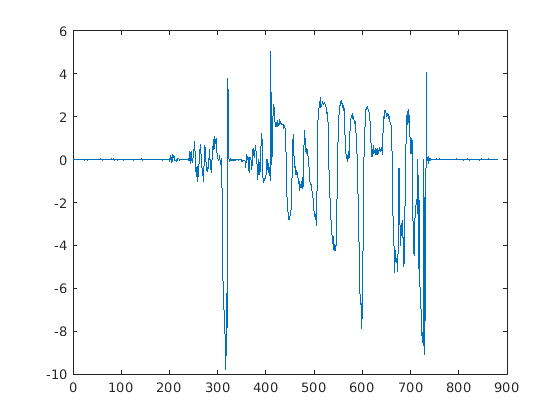

clc; clear; close all;
x = load("variable_a2.txt");
for i = 1:length(x)
    if x(i) > 15
        x(i) = 9.81;
    elseif x(i) < 0;
        x(i) = 0;
    end
end

for i = 1:length(x)
    x(i) = x(i) - 9.81;
end
y = load("variable_b2.txt");
y = normalize(y, "range");

plot(x)

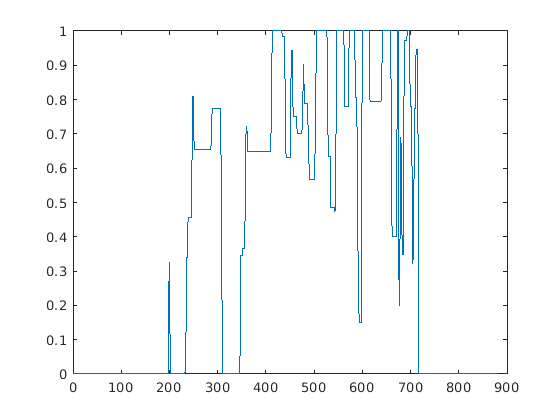

plot(y)


format long
b1 = x\y

b1 =    0.021716404511110


yCalc1 = b1*x;
scatter(x,y)
hold on
plot(x,yCalc1)
xlabel('acceleration')
ylabel('pwm_speeds')
grid on
X = [ones(length(x),1) x];
b = X\y

b =    0.386919443797210
   0.049316369550244


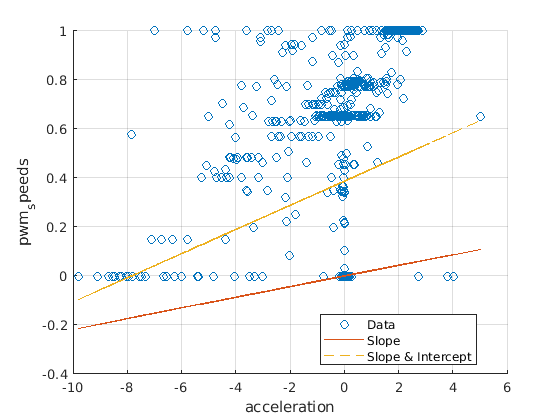

yCalc2 = X*b;
plot(x,yCalc2, '--')
legend('Data','Slope','Slope & Intercept','Location','best');
hold off


% normaliser pwm signal - Det har vi gjort nu :) 
% Tag højde for massen hvis vi hiver det ud i newton - Det gør de selv i
% blokken der styrer polynomiet som vi er ved at lave. 
% Fix tyngdekraften siden signalet ikke er 0 når den står stille i luften
% men 9.81.